# Magnetic Circuit concepts

B = ?; % flux density (Wb/m^2 / T) 
u = ?; % permeability of the material

H = u*B; % field intensity 

To develop magnetic circuit analysis ,

let the amterial be linear

let the cross-sectional area expose to the magneitc flux density B grows to a nondifferential size ( any size that is fixed)


$$\phi =\int B_z \left(x,y\right)\;\textrm{dx}\;\textrm{dy}$$


or eaiser,

$\phi =\textrm{BA}$, where B is the constant flux density and A is the cross sectional area of the block

Once have the phi , 

stretching the block in the z-direction , the flux $\phi$flows through each succeeding layer of thickness creating a change in the magnetic field intensity 

$F=\int \textrm{Hdz}=\textrm{Hl}$, F magnetomotive force (A) , l the length of z (m)

## case 1 : box

A = ?;
phi = B * A;
F = H*l;


P = u*A/l; % permeance of the material
R = 1/P ; % reluctance 

phi = P * F ;


## Magnetic Field Sources

two common sources of magnetic fields : 

- current flowing in a wire

- permanent magnet

1) Current 


$$I=\oint_C H\ldotp \textrm{dl}$$
 

if C enclosed path or contour 

I is the total current enclosed by the contour

H . dl is the vecotr dot product between the vector field internsity and a differential vector dl on the contour 

Positive current is defined as flowiing in the direction of a right hand rule in the direction of the enclosed path 


$$I=\mathrm{NI}=\int_a^b H_{\mathrm{ab}} \mathrm{dz}+\;\int_b^c H_{\mathrm{bc}} \mathrm{dr}+\int_c^d H_{\mathrm{cd}\left(\right.} \left(-\mathrm{dz}\right)+\int_d^a H_{\mathrm{da}} \left(-\mathrm{dr}\right)$$


## Air Gap Modelling



p_ag_model = '1';

u = 4*pi*10^-7; % permeability of free space (usually air )
g = ?; % air gap length
w = ?; % width
l = ?;

if p_ag_model =='1'
    
    A = w*l; % cross section area

    p_ga = u * A/g; % see below example a

elseif p_ag_model == '2'
    
    A = w*l + w*2*g;

    p_ga = u*(w*(l+2*g))/g; % see below example b

elseif p_ag_model == '3'

    A = w*l;

    P_s = u*A/g;

    func = @(x) u*L/(g+pi*x);
    Xmax = ; % no more than 10 times the gap length
    P_f = integral(func,0,Xmax);
    P_ga = Ps + P_f; % see below example c
end





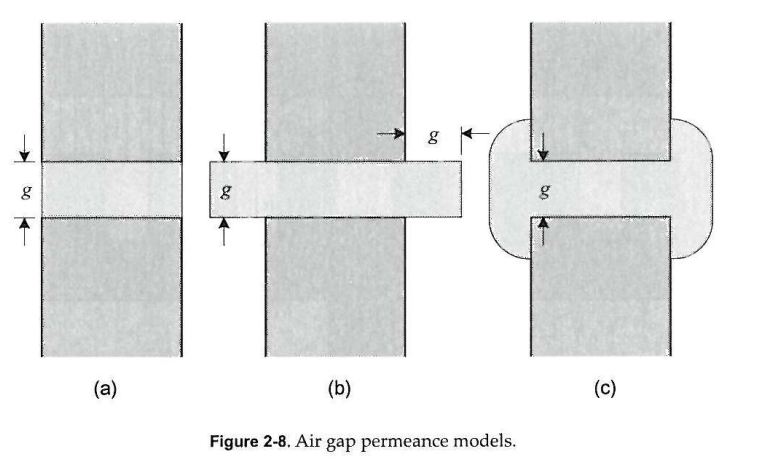

Better look of ©

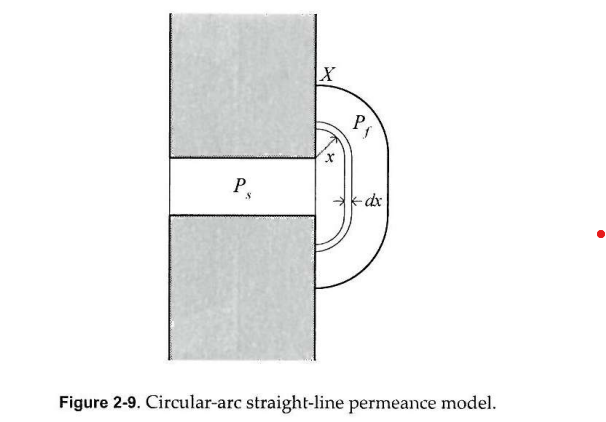

## Slot modelling

L = ?; % ldepth of the structureTs = ?; % total width
A = L*Ts; % cross section area (total width *  L)
g = ? ; % gap length


s_model = '1';
effective_gap_model = '1'
if s_model  == '1'

    Pg = u * A/g; 
    % a poor approximation because the relative 
    % permeability of the slot is orders of magnitude lower than that of block material
    % be the upper bound

elseif s_model == '2'
    L =  % this is the depth
    ws =  % slot gap
    Pg = u*(A-ws*L)/g;

    % ignore the flux crossing the gap over the slot 
    % lower bound the permeance 
elseif s_model == '3'

    % this method is based on the observation that the flux crossing the
    % gap over the slot travels a further distance before 
    % reaching the highly permeable material across the gap

    ws = ?;      % slot width in meters
    tau_s = ?;      % slot pitch in meters
    
    if effective_gap_model == '1'
        % Carter's coefficient - First approximation
        denom1 = tau_s * ((5 * g / ws + 1) / ws);
        Kc = 1 / (1 - 1 / denom1);  % equivalent to (1 - 1/denom1)^(-1)
    elseif effective_gap_model == '2'
        % Carter's coefficient - Second approximation
        term1 = ws / (2 * g);
        term2 = g / ws * log(1 + 0.25 * (ws / g)^2);
        Kc = 1 / (1 - (2 * ws / (pi * tau_s)) * (atan(term1) - term2));

    % Effective air gap lengths
    ge = Kc * g;

    % Permeance
    Pg = mu0 * A / ge;

elseif s_model == '4' 
    Pg = u * L * (wt/g + 4/pi * ln(1+ pi* ws/4/g));
end



%% Electrical and Mechanical R